i = 1, C = 1, P = 0.007313,sum_v = 10.2162
i = 2, C = 101.0991, P = 0.58708,sum_v = 8.1124
i = 3, C = 201.1982, P = 1.0271,sum_v = 7.1318
i = 4, C = 301.2973, P = 1.4048,sum_v = 6.5134
i = 5, C = 401.3964, P = 1.7341,sum_v = 6.0352
i = 6, C = 501.4955, P = 2.0457,sum_v = 5.6986
i = 7, C = 601.5946, P = 2.3439,sum_v = 5.443
i = 8, C = 701.6937, P = 2.6411,sum_v = 5.2582
i = 9, C = 801.7928, P = 2.9081,sum_v = 5.0669
i = 10, C = 901.8919, P = 3.1784,sum_v = 4.9233
i = 11, C = 1001.991, P = 3.4361,sum_v = 4.7907
i = 12, C = 1102.0901, P = 3.7199,sum_v = 4.7153
i = 13, C = 1202.1892, P = 3.9554,sum_v = 4.5964
i = 14, C = 1302.2883, P = 4.259,sum_v = 4.5688
i = 15, C = 1402.3874, P = 4.5238,sum_v = 4.5064
i = 16, C = 1502.4865, P = 4.801,sum_v = 4.4639
i = 17, C = 1602.5856, P = 5.0045,sum_v = 4.3625
i = 18, C = 1702.6847, P = 5.3082,sum_v = 4.3552
i = 19, C = 1802.7838, P = 5.6142,sum_v = 4.3505
i = 20, C = 1902.8829, P = 5.8127,sum_v = 4.2674
i = 21, C = 2002.982, P = 6.1134,sum_v = 4.263

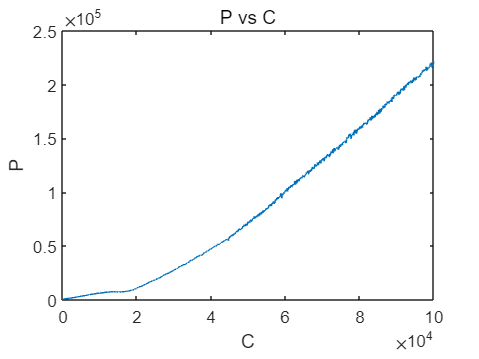

The maximum value of P is 218.52 at C = 99299.31


w = 2.2143; %入射波浪频率

T = (2*pi)/w;
h = 0.0001; %步进长度
m_fz = 4866; %浮子的质量
m_z = 2433; %振子的质量
m_fu = 1165.992; %垂荡附加质量
S = m_fz + m_fu; %受力分析考虑的总质量
c_x = 167.8395; %垂荡兴波阻尼系数
rho = 1025; %海水密度
g = 9.8; %重力加速度
A = pi; %圆柱底面积
zf = 4890; %垂荡激励力振幅 就是f

K_t = 80000; %弹簧刚度
B = rho*g*A;
V = (0.8*A)/3; %圆锥体积

K_zn_values = linspace(1, 100000, 1000); % K_zn的值
P_values = zeros(size(K_zn_values)); % 用于存储每个K_zn对应的P值

for idx = 1:length(K_zn_values)
    K_zn = K_zn_values(idx);
    % 创建计算结果xyzm的数组
    t = 200:h:400;
    N = length(t);
    x = zeros(1,N);
    y = zeros(1,N);
    z = zeros(1,N);
    m = zeros(1,N);

    % 四阶龙格库塔迭代
    for i = 2:N
        t_n = t(i-1);
        x_n = x(i-1); % 浮子的位移
        y_n = y(i-1); % 振子的位移
        z_n = z(i-1); % z_n = u(t)浮子
        m_n = m(i-1); % m_n = w(t)振子

        % 写一阶微分方程
        kx1 = z_n; 
        ky1 = m_n; 
        kz1 = (zf*cos(w*t_n) + K_zn*(m_n - z_n) + K_t*(y_n - x_n) - c_x*z_n - B*x_n) / S; % u'(t)
        km1 = -(K_zn*(m_n - z_n) + K_t*(y_n - x_n)) / m_z;

        kx2 = z_n + kz1*h/2;
        ky2 = m_n + km1*h/2;
        kz2 = (zf*cos(w*(t_n + h/2)) + K_zn*(m_n + km1*h/2 - z_n - kz1*h/2) + K_t*(y_n + ky1*h/2 - x_n - kx1*h/2) - c_x*(z_n + kz1*h/2) - B*(x_n + kx1*h/2)) / S; 
        km2 = -(K_zn*(m_n + km1*h/2 - z_n - kz1*h/2) + K_t*(y_n + ky1*h/2 - x_n - kx1*h/2)) / m_z;

        kx3 = z_n + kz2*h/2;
        ky3 = m_n + km2*h/2;
        kz3 = (zf*cos(w*(t_n + h/2)) + K_zn*(m_n + km2*h/2 - z_n - kz2*h/2) + K_t*(y_n + ky2*h/2 - x_n - kx2*h/2) - c_x*(z_n + kz2*h/2) - B*(x_n + kx2*h/2)) / S; 
        km3 = -(K_zn*(m_n + km2*h/2 - z_n - kz2*h/2) + K_t*(y_n + ky2*h/2 - x_n - kx2*h/2)) / m_z;

        kx4 = z_n + kz3*h;
        ky4 = m_n + km3*h;
        kz4 = (zf*cos(w*(t_n + h)) + K_zn*(m_n + km3*h - z_n - kz3*h) + K_t*(y_n + ky3*h - x_n - kx3*h) - c_x*(z_n + kz3*h) - B*(x_n + kx3*h)) / S; 
        km4 = -(K_zn*(m_n + km3*h - z_n - kz3*h) + K_t*(y_n + ky3*h - x_n - kx3*h)) / m_z;

        x(i) = x_n + h/6*(kx1 + 2*kx2 + 2*kx3 + kx4);
        y(i) = y_n + h/6*(ky1 + 2*ky2 + 2*ky3 + ky4);
        z(i) = z_n + h/6*(kz1 + 2*kz2 + 2*kz3 + kz4);
        m(i) = m_n + h/6*(km1 + 2*km2 + 2*km3 + km4);
    end

    deter_v = (m - z).^2;
    sum_v = sum(deter_v);
    P = K_zn * sum_v * h * (1/200);
    P_values(idx) = P;
end

plot(K_zn_values, P_values, 'b');
xlabel('直线阻尼系数');
ylabel('P');

% 找到最大值及其对应的索引
[max_P, idx_max] = max(P_values);
max_K_zn = K_zn_values(idx_max);


